# Load resources

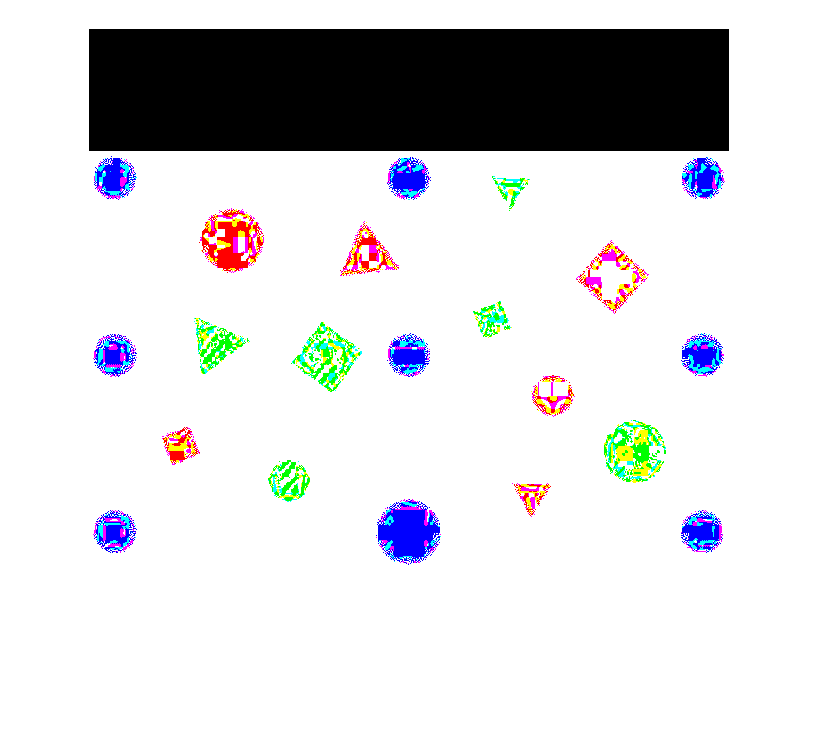

clear All; close all;
capture = double(imread("capture.jpg"));
start = double(imread("TestSheet1.jpg"));
goal = double(imread("TestSheet8.jpg"));


% Zero the text part
plainImage = capture;
plainImage(1:122,:,:) = 0;
% plainImage = plainSpace(:,1:3015,:);  %double(plainspace(60:4619,129:2995,:));
imshow(plainImage)

## Run

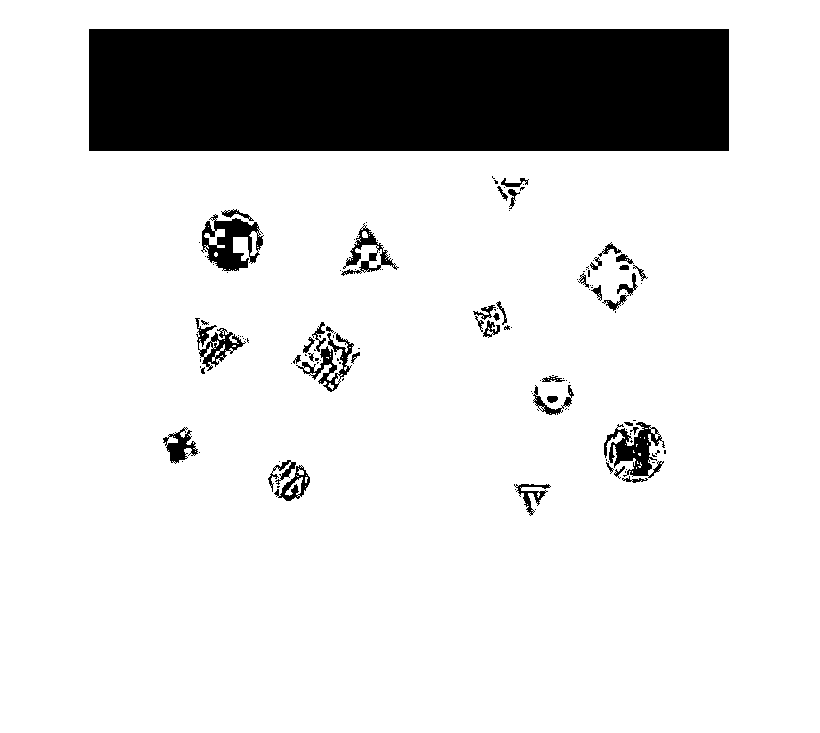


% Get colour plains
red = plainImage(:,:,1);
green = plainImage(:,:,2);
blue = plainImage(:,:,3);
imshow(blue)

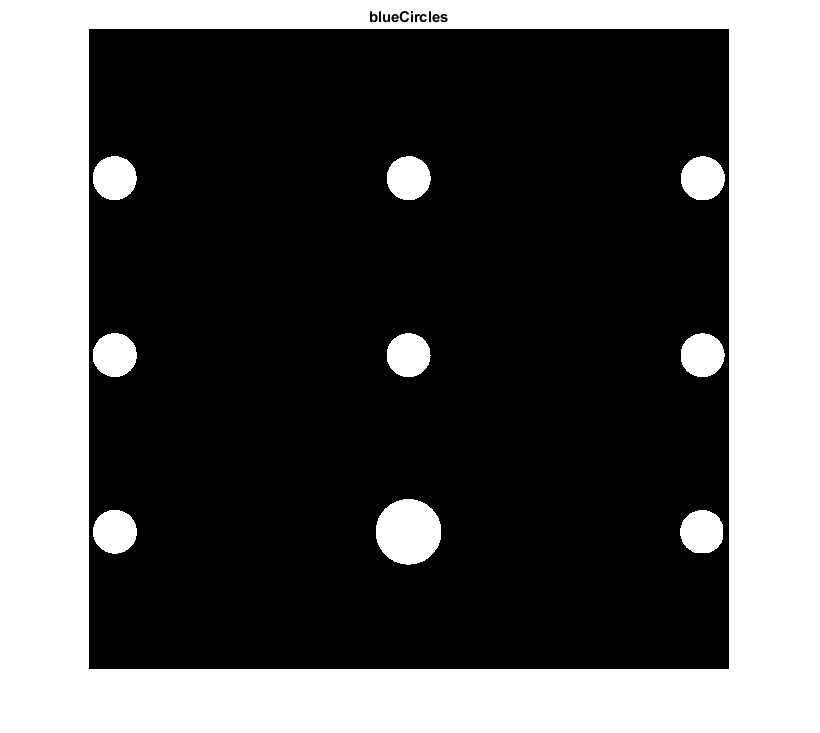


% Clean noise, Get blue circles
blueCircles = imclose(blue./(red+green+blue) > 0.6, ones(5,5));
figure; imshow(blueCircles); title("blueCircles");

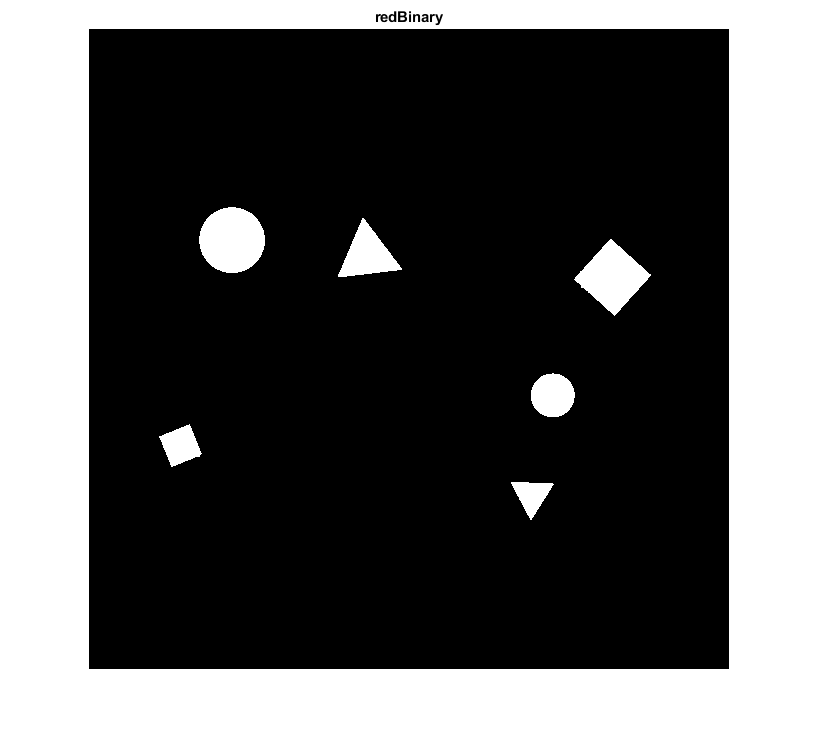


% get red shapes
% Old method to filter noise: redBinary = medfilt2(red./(red+green+blue) > 0.45, [3,3]);
redBinary = imclose(red./(red+green+blue) > 0.5, ones(10,10));
figure; imshow(redBinary); title("redBinary");

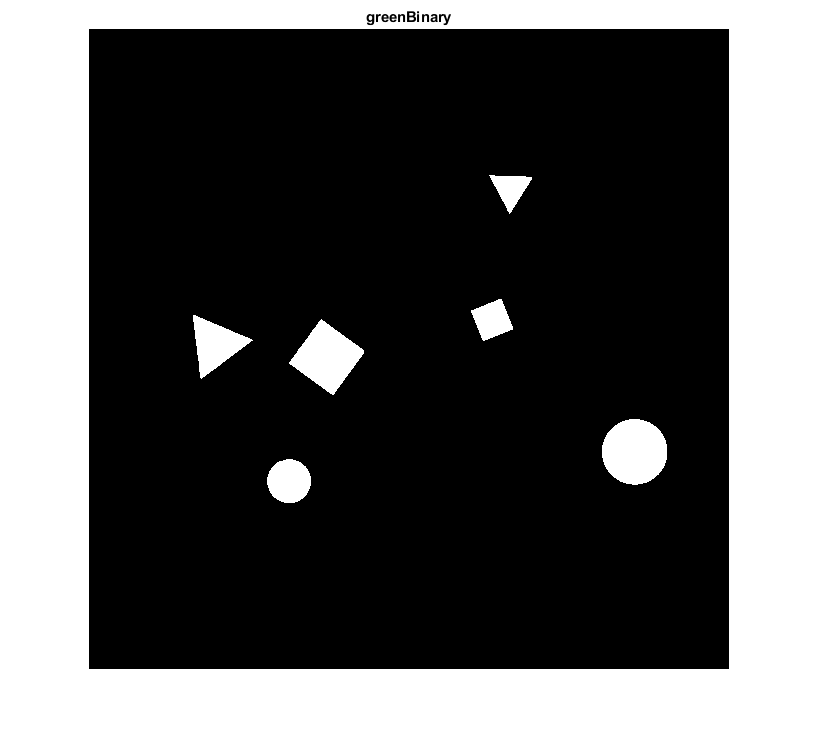


% Get green shapes
green = green./(red+green+blue) > 0.5;
greenBinary = imclose(green, ones(5,5));
figure; imshow(greenBinary); title("greenBinary"); 

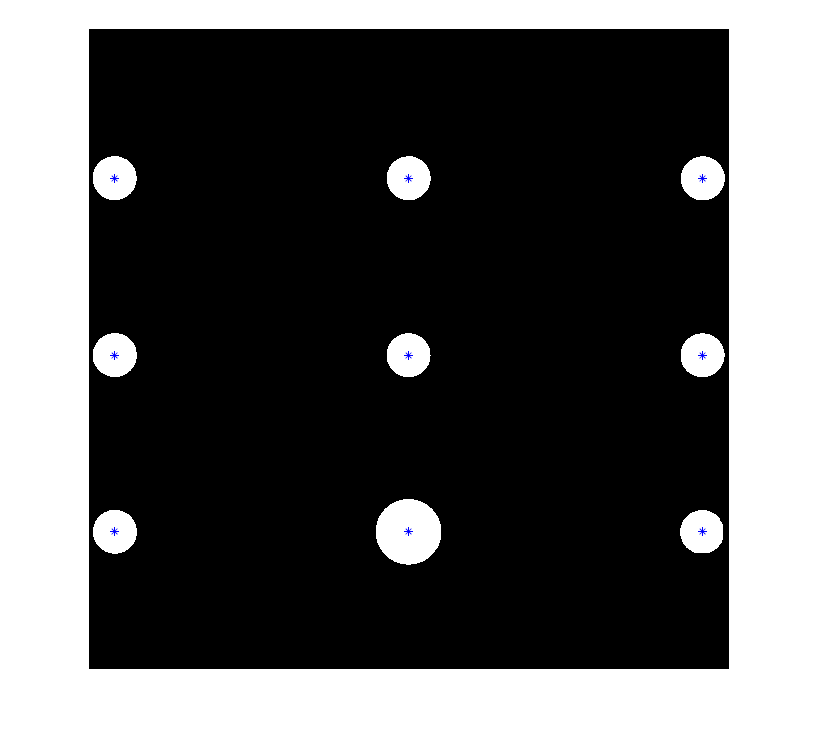


% Get data from sheet
% Get blue centroids
blueStats = regionprops("table",blueCircles,"Centroid","Area","Circularity");
imshow(blueCircles)
hold on
plot(blueStats.Centroid(:,1),blueStats.Centroid(:,2),"b*")
hold off

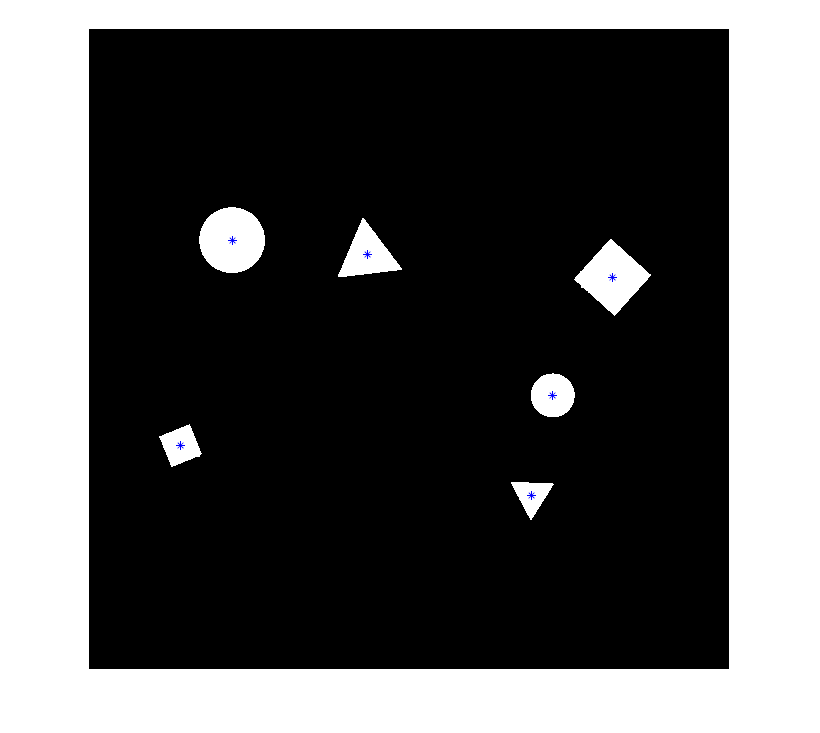


% Get red centroids
redStats = regionprops("table",redBinary,"Centroid","Area","Circularity");
imshow(redBinary)
hold on
plot(redStats.Centroid(:,1),redStats.Centroid(:,2),"b*")
hold off

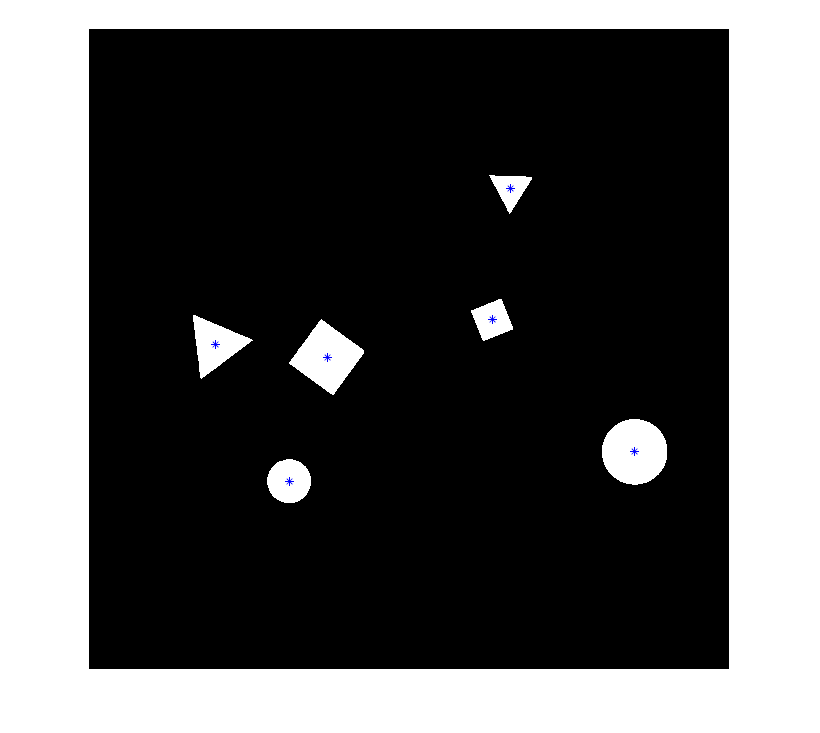


% Get green centroids
greenStats = regionprops("table",greenBinary,"Centroid","Area","Circularity");
imshow(greenBinary)
hold on
plot(greenStats.Centroid(:,1),greenStats.Centroid(:,2),"b*")
hold off


%create single array of sheet data
tasksheet = data(blueStats,"blue",100000);
tasksheet2 = data(redStats,"red",100000);
tasksheet3 = data(greenStats,"green",100000);
%combine them together
tasksheet = cat(1,tasksheet,tasksheet2);
tasksheet = cat(1,tasksheet,tasksheet3);


%Goal and Start
[redStartStats,blueStartStats,greenStartStats] = colourExtraction(start);
[redGoalStats,blueGoaltStats,greenGoalStats] = colourExtraction(goal);

%create single array of goal data
%allStarts = data(blueStartStats,"blue",32000);
allStarts = data(redStartStats,"red",32000);
allStarts3 = data(greenStartStats,"green",32000);
%combine them together
%allStarts = cat(1,allStarts,allStarts2);
allStarts = cat(1,allStarts,allStarts3);

%create single array of goal data
%allGoals = data(blueStartStats,"blue",32000);
allGoals = data(redStartStats,"red",32000);
allGoals3 = data(greenStartStats,"green",32000);
%combine them together
%allGoals = cat(1,allGoals,allGoals2);
allGoals = cat(1,allGoals,allGoals3);

%homogenous coordinates
%manual retrieval from tasksheet matrix
P= [281.9187 212.8668;281.9187 4465.4745;2841.4565 4466.109;282.5802 4465.4745];
%retrieved from tasksheet on teams
Q = [20 290; 345 560; 345 30; 20 20];
H = simple_homography(P, Q);

Error using vgg_condition_2d (line 12)
rows != 2 or 3

Error in vgg_H_from_x_lin (

function [redStats,blueStats,greenStats] = colourExtraction(image)
red = image(:,:,1);
green = image(:,:,2);
blue = image(:,:,3);
Red = red./(red+green+blue) > 0.5;
Blue = blue./(red+green+blue) > 0.5;
Green = green./(red+green+blue) > 0.5;
if sum(sum(Red))>0
    redStats = regionprops("table",Red,"Centroid","Area","Circularity");
else
    redStats = 0;
end
if sum(sum(Blue))>0
    blueStats = regionprops("table",Blue,"Centroid","Area","Circularity");
else
    blueStats = 0;
end
if sum(sum(Green))>0
    greenStats = regionprops("table",Green,"Centroid","Area","Circularity");
else
    greenStats = 0;
end
end

function whole = data(arrayIn,colour,areaSize)
[rownum,~]=size(arrayIn);
for c = 1:rownum
    whole(c,2)=colour;
    if arrayIn.Circularity(c,:)>0.85
        whole(c,7)= "Circle";
    elseif arrayIn.Circularity(c,:)<=0.85 && arrayIn.Circularity(c,:)>0.7
        whole(c,7)= "Square";
    elseif arrayIn.Circularity(c,:)<=0.70
        whole(c,7)= "Triangle";
    end
    if arrayIn.Area(c,1)>areaSize
        whole(c,11)= "True";
    else
        whole(c,11)= "False";
    end
    whole(c,8)= arrayIn.Centroid(c,1);
    whole(c,9)= arrayIn.Centroid(c,2);
    whole(c,10)= arrayIn.Area(c,1);
end
end